L1=25e-3; %side length
M=5000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
lambda=0.5*10^-6; %wavelength
k=2*pi/lambda; %wavenumber
w=0.051; %source half width (m)

%parameters for HG00 input signals
w_in = 0.5e-3;        %width of HG00 signal
d = 10e-4;           %distance between centers of neighbour gaussian beams
f = 0.25;           %focus length of lens
r = 0.0125          %radius of lens

r = 0.0125

P=circle_window(x1,y1,r); %window for lens.

%generate two HG00 input signals

[X1,Y1]=meshgrid(x1,y1);

uin =  zeros(length(X1),length(Y1));
for i = -1:1
    for j = -1:1
        xc = d*i;
        yc = d*j;
        uin = uin +  exp(-((X1-xc).^2 + (Y1-yc).^2)/(w_in^2));
    end
end

I1=abs(uin.^2); %src irradiance


%Plot input signal 

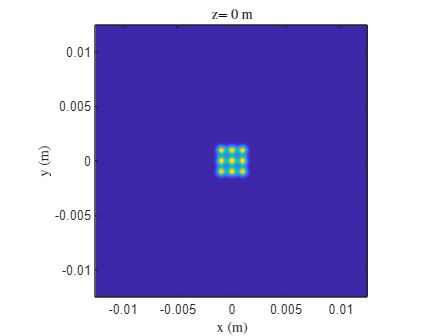

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('z= 0 m')

% uout=propTF(uin,L1,lambda,f); %propagation
uout=propIR(uin,L1,lambda,f); %propagation
% uout = uout.*P;
uout=focus(uout,L1,lambda,f); %phase screen for first lens
% uout=propTF(uout,L1,lambda,f); %propagation
uout=propIR(uout,L1,lambda,f); %propagation

x2=x1; %obs coords
y2=y1;
I2=abs(uout.^2); %obs irrad


%Plot output signal

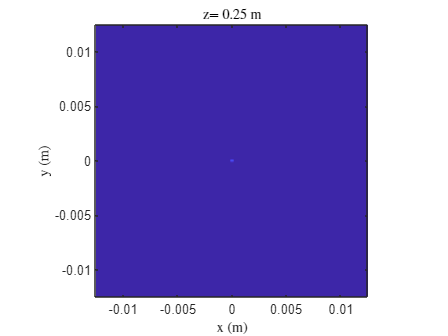

figure(2) %display obs irrad
imagesc(x2,y2,nthroot(I2,3));%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(f),' m']);

uout=propIR(uout,L1,lambda,f); %propagation
I2=abs(uout.^2); %obs irrad

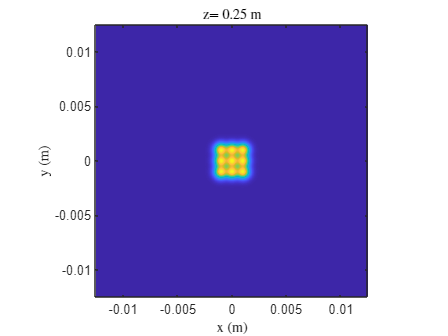


figure(3) %display obs irrad
imagesc(x2,y2,nthroot(I2,3));%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(f),' m']);


uout=focus(uout,L1,lambda,f);
uout=propIR(uout,L1,lambda,f); %propagation
I2=abs(uout.^2); %obs irrad

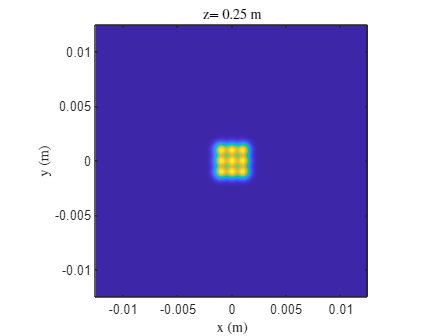


figure(4) %display obs irrad
imagesc(x2,y2,nthroot(I2,3));%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(f),' m']);